%SM: Can we change variable name "pop" into "popularity"? I didn't get it at first...
%SM: and y and x in longitude and latitude?

%ST: All Sights used in Berlin as Data-Structures
centralStation = struct("y", 52.52514262794553, "x", 13.369401998549902, ...
    "id", 1, "price", 0, "pop", 0, "duration", 0, "name", "station");
brandenburgGate = struct("y", 52.51640515728868, "x", 13.377704098549703, ...
    "id", 2, "price", 0, "pop", 1, "duration", 30, "name", "gate");
reichstagBuilding = struct("y", 52.51873769328525, "x", 13.376208656220577, ...
    "id", 3, "price", 0, "pop", 2, "duration", 120, "name", "reichstag");
memorial = struct("y", 52.514104081035704, "x", 13.378680512043356, ...
    "id", 4, "price", 0, "pop", 3, "duration", 30, "name", "memorial");
eastSideGallery = struct("y", 52.505257448032204, "x", 13.439771749277382, ...
    "id", 5, "price", 0, "pop", 4, "duration", 45, "name", "eastSide");
checkpointCharlie = struct("y", 52.5075750694616, "x", 13.390364769714038, ...
    "id", 6, "price", 0, "pop", 10, "duration", 45, "name", "charlie");
tvTower = struct("y", 52.521069579218974, "x", 13.40920452184171, ...
    "id", 7, "price", 20.5, "pop", 8, "duration", 120, "name", "tvTower");
oldNationalGallery = struct("y", 52.52096052837539, "x", 13.398309983208197, ...
    "id", 8, "price", 10, "pop", 6, "duration", 150, "name", "oldNational");
ddrMuseum = struct("y", 52.51971144874204, "x", 13.402700296701948, ...
    "id", 9, "price", 9.8, "pop", 9, "duration", 90, "name", "ddr");
techMuseum = struct("y", 52.498789620642924, "x", 13.377916785055444, ...
    "id", 10, "price", 8, "pop", 5, "duration", 180, "name", "tech");
zoo = struct("y", 52.508037121902355, "x", 13.337754698549514, ...
    "id", 11, "price", 16, "pop", 7, "duration", 150, "name", "zoo");

%ST: destSights contains all Sight-structs above
destSightsBerlin = [centralStation,brandenburgGate,reichstagBuilding,...
    memorial,eastSideGallery,checkpointCharlie,tvTower,oldNationalGallery...
    ddrMuseum,techMuseum,zoo];



%SM: All Sights used in PARIS as Data-Structures
parisEst = struct("y", 48.8758535, "x", 2.3600134, ...
    "id", 21, "price", 0, "pop", 0, "duration", 0, "name", "parisEst");
eiffelTower = struct("y", 48.8561446, "x", 2.2978204, ...
    "id", 22, "price", 20.0, "pop", 1, "duration", 120, "name", "eiffelTower");
louvre = struct("y", 48.8624906, "x", 2.3360431, ...
    "id", 23, "price", 17.0, "pop", 6, "duration", 180, "name", "louvre");
notreDam = struct("y", 48.8527101, "x", 2.3519702, ...
    "id", 24, "price", 0, "pop", 7, "duration", 15, "name", "notreDam");
arcDeTriomphe = struct("y", 48.8737673, "x", 2.2954441, ...
    "id", 25, "price", 13.0, "pop", 2, "duration", 45, "name", "arcDeTriomphe");
museeDOrsay = struct("y", 48.8599179, "x", 2.3265828, ...
    "id", 26, "price", 14.0, "pop", 5, "duration", 180, "name", "museeDOrsay");
centreGP = struct("y", 48.8607767, "x", 2.3517423, ...
    "id", 27, "price", 14.0, "pop", 8, "duration", 180, "name", "centreGeorgesPompidou");
basilikaSC = struct("y", 48.8868058, "x", 2.3430153, ...
    "id", 28, "price", 8.0, "pop", 4, "duration", 90, "name", "basilikaSacreCoeur");
avenueDesCE = struct("y", 48.8659369, "x", 2.31967728, ...
    "id", 29, "price", 0, "pop", 3, "duration", 60, "name", "avenueDesCampsElysees");


%SM: destSightsParis contains all sight-seeings of Paris above
destSightsParis = [parisEst,eiffelTower,louvre,...
    notreDam,arcDeTriomphe,museeDOrsay,centreGP,basilikaSC...
    avenueDesCE];

%ST: Output all cities in console
%for city = destSights
    %disp(city)
%end

%SM: choose sightseeing here
%SM: create an array with strings of cities
cityStrings = ["Berlin", "Paris", "Rome", "Tokyo" ];

%SM: choose a city
city = cityStrings(2)

city = "Paris"


%SM: check a parameter
popularity = false

popularity = logical
   0


price = false

price = logical
   0


visiting_time = false

visiting_time = logical
   0


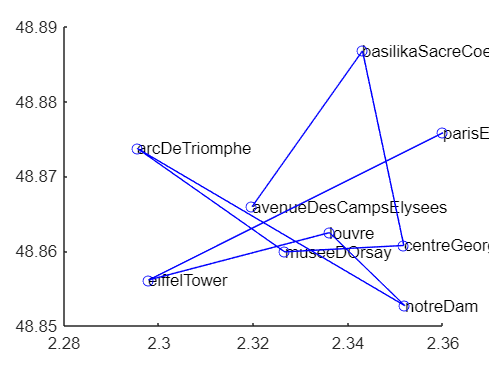


%SM: in the future: use it like "if(popularity) doStuff()"


%SM: results of different cities
if (city == "Berlin")
    %SM: clear figures for a better plot
    clf(figure(1))
    clf(figure(2))

    destSights = destSightsBerlin;

elseif (city == "Paris")
    clf(figure(1))
    clf(figure(2))

    destSights = destSightsParis;

%SM: not implemented yet
    %elseif (city == "Rome")
%    destSights = destSightsRome;
%elseif (city == "Tokyo")
%    destSights = destSightsTokyo;
end


figure(1);
text([destSights(:).x],[destSights(:).y],[destSights(:).name])
hold on;
plot([destSights(:).x],[destSights(:).y],'bo-')



% ST:                           Algorithm Edit Comments
% For variable and param explanation please visit TSP_ACO
%    SETTING PARAMS     %
% exploit vs explore
q_0 = .2770;
numAnts = 200;
beta = 1;
maxIts = 200;
Q = 1;
rho = .4817;

params = struct('q_0', q_0, 'numAnts', numAnts, 'beta', beta, 'Q', Q, 'rho', rho);

fprintf('Running Berlin Sightseeing Optimization on  %i Sights with the following parameters:\n', length(destSights));

Running Berlin Sightseeing Optimization on  9 Sights with the following parameters:


disp(params);

        q_0: 0.2770
    numAnts: 200
       beta: 1
          Q: 1
        rho: 0.4817



% Tau will be populated dynamically, blank for now
tau = ones(length(destSights),length(destSights));
% Eta is a static matrix based on a known heuristic with known inputs
% so we can simply populate it now in advance
eta = genEta(destSights);

% Creates an ititial path
bestPath = 1:length(destSights);
bestScore = scorePath(bestPath, destSights);
fprintf('Initial Score: %f', bestScore);

Initial Score: 0.342550

numIts = 1;
scores = zeros(1, maxIts);

while numIts < maxIts;
	% for ant_k in colony
	for ant_k = 1:numAnts
		
		% Init empty path and place ant_k at a random starting index
		path = zeros(1, length(destSights));
		currInd = 1;
		path(currInd) = randi(length(destSights));
		
		% Need to track of where we have not been
		unvisited = 1:length(destSights);
		unvisited(path(1)) = [];
		
		
		% While ant has not visited all cities
		for currInd = 1:(length(destSights) - 1)
			r = path(currInd);
			
			% Here we find the destination city s
			if (rand < q_0)
				[~, sInd] = max(tau(r, unvisited) .* eta(r, unvisited).^beta);
				s = unvisited(sInd);
			else
				vec = tau(r, unvisited) .* (eta(r, unvisited).^beta);
				probs = vec ./ sum(vec);
				
				% Sometimes prob vec is a zero vector, giving nans. In
				% this case they are all equally bad so we choose 1st
				if any(isnan(probs))
					sInd = 1;
				else
					
					% Draws the city to visit based on the above probabilities:
					%    The ways this works is that the ith element of probs
					%    defines the probability of selecting ith element of
					%    unvisited array. Thus if we want to draw an element
					%    based on this distribution, we treat the probabilities
					%    as a partitioning of the unit interval. We then choose
					%    a partition by generating a random number and then
					%    selecting the interval in which the number lies. By
					%    taking the cumulative sum of the probabilities, we get
					%    the partitions of the unit interval. We then compare
					%    this to the random number, the first nonzero element
					%    of the resulting logical array is the chosen element
					%    of the unvisited array
					sInd = find(cumsum(probs) > rand, 1);
				end
				s = unvisited(sInd);
			end
			
			% Add s to the path and remove it from the unvisited list
			path(currInd + 1) =  s;
			unvisited(sInd) = [];
		end
		
		score = scorePath(path, destSights);
		if (score < bestScore)
			bestScore = score;
			bestPath = path;
		end
		
		% Now we need to update tau with the pheromones left by this ant:
		toCities = circshift(path, [0,1]);
		% 		tau(sub2ind([numCities numCities], path, toCities)) = tau(sub2ind([numCities numCities], path, toCities)) +  Q / score;
		
		for ind = 1:length(destSights)
			fromCity = path(ind);
			toCity = toCities(ind);
			tau(fromCity, toCity) = tau(fromCity, toCity) + Q / score;
		end
    end
	scores(numIts) = bestScore;
	% Perform the pheromone evaporation
	tau = (1 - rho) * tau;
	
	numIts = numIts + 1;
end

%ST: Display best score at the end.
disp(bestScore);

    0.1742



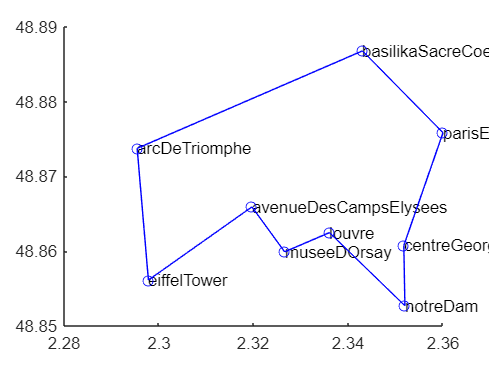

figure(2);
text([destSights(:).x],[destSights(:).y],[destSights(:).name])
hold on;
plot([destSights(bestPath).x destSights(bestPath(1)).x],  [destSights(bestPath).y destSights(bestPath(1)).y], 'bo-');


%ST: Commented out score figure as not important for now
%figure(3);
%plot(1:maxIts, scores);